load memories.dat

memories

memories =      1     1     1     1     0     0     1     0     0     1     0     1     0     0     1     0     1     0     0     1     0     1     1     1     0
     1     1     1     1     1     0     0     0     1     0     0     0     0     1     0     1     0     0     1     0     1     1     1     0     0
     0     1     1     1     1     1     0     0     0     0     1     0     0     0     0     1     0     0     0     0     0     1     1     1     1
     1     0     0     0     1     1     1     0     1     1     1     0     1     0     1     1     0     0     0     1     1     0     0     0     1
     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0
     0     1     1     1     0     1     0     0     0     0     0     1     1     1     0     0     0     0     0     1     0     1     1     1     0


% Plot the stored memories
colormap gray; 
cmap = colormap; 
cmap = flipud(cmap); 
colormap(cmap);

% Testing State Recovery with N = 5 stored memories

figure(1); clf
N = 5 % define number of stored memories

N = 5


storedMems = memories(1:N, :)

storedMems =      1     1     1     1     0     0     1     0     0     1     0     1     0     0     1     0     1     0     0     1     0     1     1     1     0
     1     1     1     1     1     0     0     0     1     0     0     0     0     1     0     1     0     0     1     0     1     1     1     0     0
     0     1     1     1     1     1     0     0     0     0     1     0     0     0     0     1     0     0     0     0     0     1     1     1     1
     1     0     0     0     1     1     1     0     1     1     1     0     1     0     1     1     0     0     0     1     1     0     0     0     1
     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0


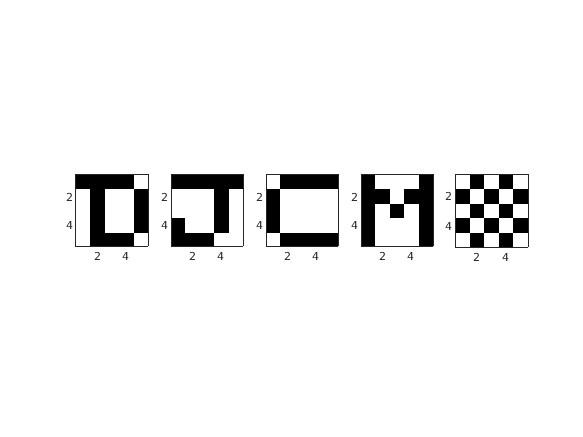


for i = 1:N
    subplot(1, N, i)
    % 1 = num grid rows
    % N = num grid cols
    % i = grid position for new axes
    
    imagesc(reshape(storedMems(i, :), 5, 5)'); 
    axis square;
end


% Now creating variable T (targets) by definition of T

% Setting memories to {-1, 1} instead of {0, 1}
I = find(storedMems == 0);
storedMems(I) = -1; 

% Initialize X to a corrupted memory (the exercise)
n = 1 % memory number

n = 1

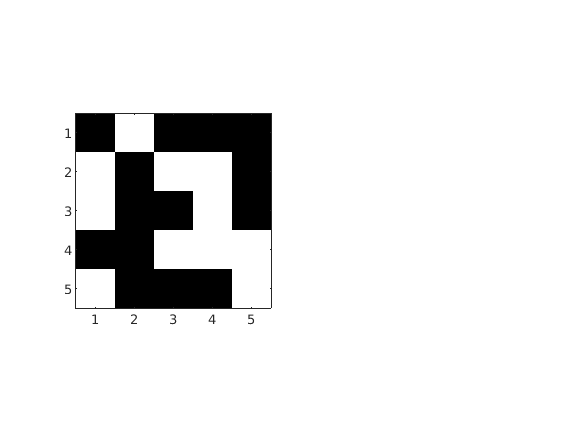

x = storedMems(n, :)';
% Corrupting some random bits
x(16, 1) = -x(16, 1);
x(2,1)  = -x(2,1);
x(5,1)  = -x(5,1);
x(20,1)  = -x(20,1);
x(13,1)  = -x(13,1);

% Plotting the bad state
figure(2); clf
%colormap(cmap);
subplot(1,2,1)
imagesc(reshape(x,5,5)');
axis square;

Error using reshape
To RESHAPE the number of elements must not change.

Error in restoreMemoryTest (line 67)
    imagesc(reshape(Xcorrupt, 5, 5)');

% making the matrix
X = storedMems;
Xcorrupt = X;
Xcorrupt(n, :) = x; 
restoreMemoryTest(X, Xcorrupt, n)